APP_st.name='APP';
APP_st.lat=36.2130;
APP_st.lon=-81.6920;
APP_st.alt=1076;
APP_st.env='con';
APP_st.footp='RB';


APP_rd=read_betsy('app_2009_2018',APP_st.name);

datevec(APP_rd.Time(1))

ans =         2009           6           2           0           0           0

datevec(APP_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(APP_rd.U0_S,[5 50 95])

ans =    -2.7975   16.8500   40.9475

prctile(APP_rd.U1_S,[5 50 95])

ans =    -2.8500   16.7500   40.6500

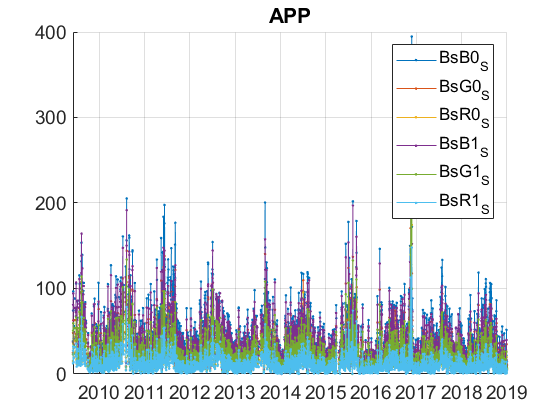

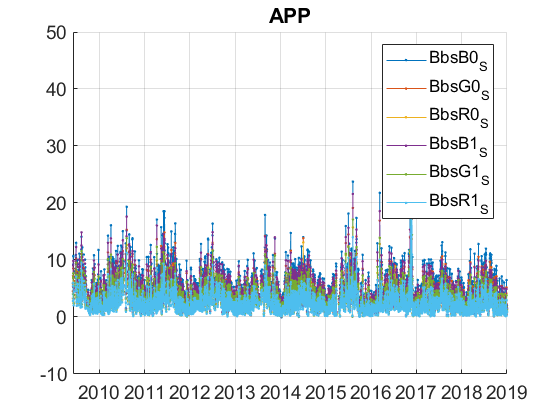

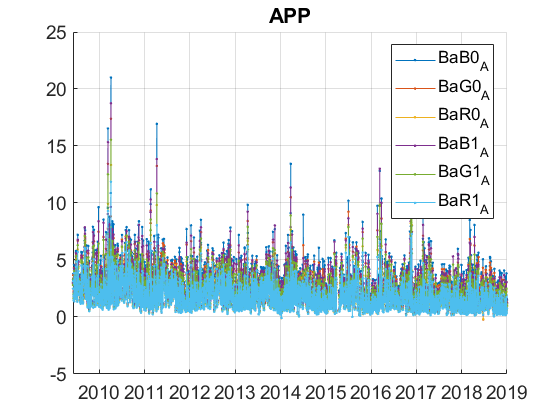

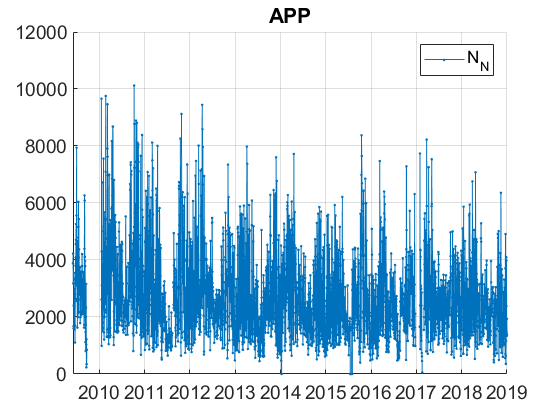

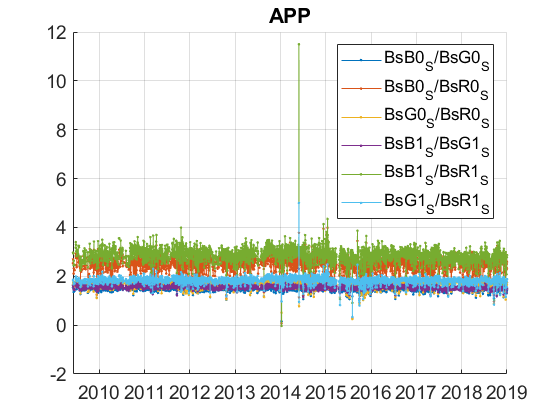

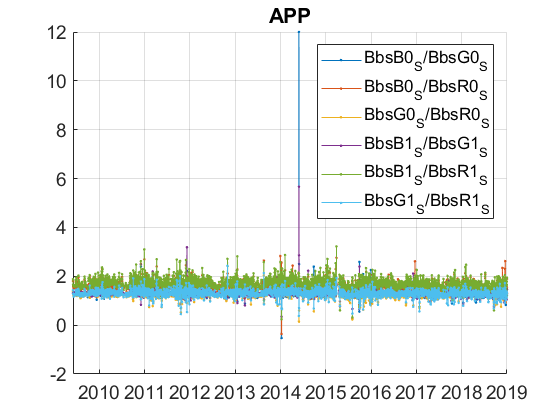

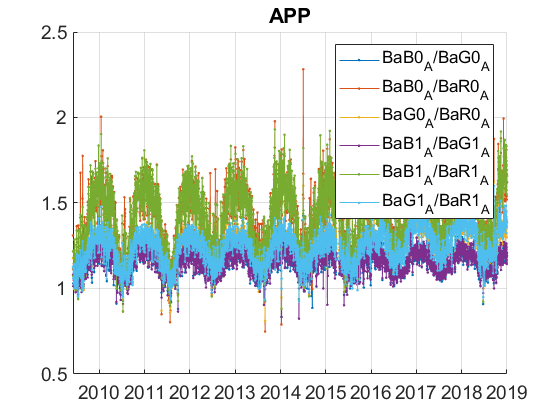

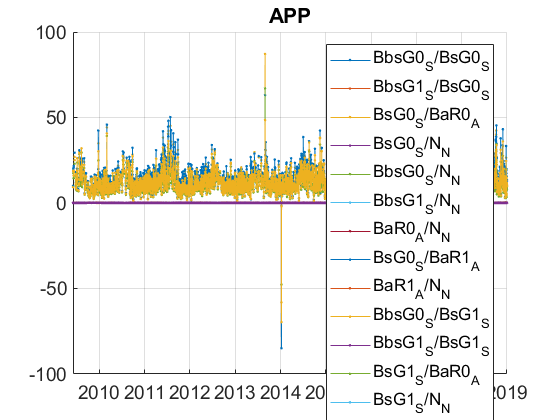

plotFigControl(APP_rd,APP_st.name);

% 2 size cut, ok
% sc: ok, max in summer, no negatives
% abs: 2 size cut, max in summer, no negatives
%very high seasonal cycle of abs ratio and abs exponent
%N:july/August 2011: too low: problem and rupture, often lower in summer

%problems:
%ratio B/R and G/R with higher max and min values since mid 2016: change PSAP --> CLAP
%should be due to the red wavelength change (660 to 653)

% ratio BbsG0/BsG1 and BbsG1/BsG1 and BbsG0/BsG0 rupture in the second part of september 2015?
% %and BbsG1/BsG0 very low in summer 2015
% SSA also show a rupture in september 2015 as well and the backscattering fraction and the exp BG

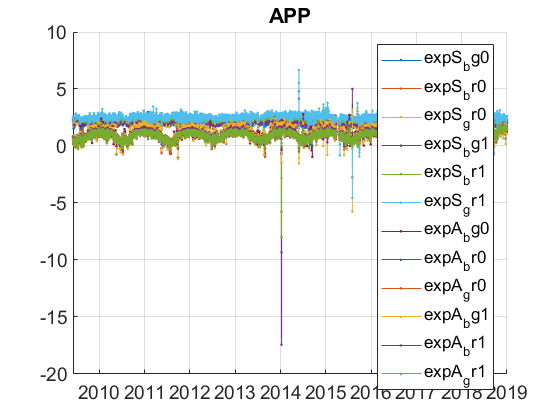

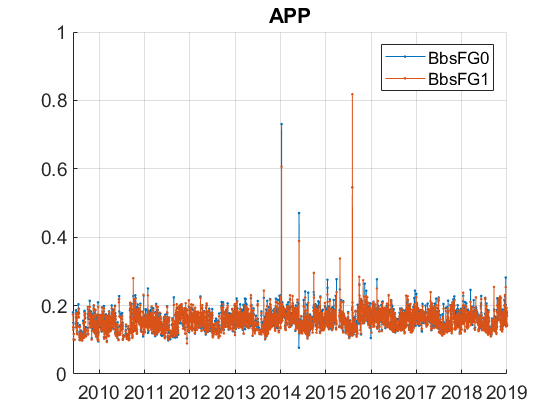

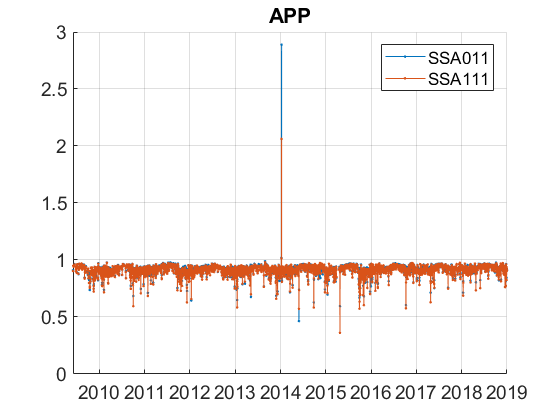

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
APP_cal=compute_exp_SSA(APP_rd,lambdaSC, lambdaAE);
plotFigControl_cal(APP_cal,APP_st.name);

%Questions:
%problems:
%abs: ratio B/R and G/R with higher max and min values since mid 2016: change PSAP --> CLAP
%should be due to the red wavelength change (660 to 653)

%sc: are the very high points in November 2016 real or bad data ?
%sc:  ratio BbsG0/BsG1 and BbsG1/BsG1 and BbsG0/BsG0 rupture in the second part of september 2015?
% %and BbsG1/BsG0 very low in summer 2015
% SSA also show a rupture in september 2015 as well and the backscattering fraction and the exp BG


APP_tr=APP_rd;
APP_tr.y=year(APP_tr.Time);
%eneleve une valeur de 2019
APP_tr=APP_tr(1:end-1,:);
% begin at the beginning of a year: 2010 (2017: 8y, 2018: 9y)
%end: 2018
P=timerange('2010-01-01','2019-01-01');
APP_tr=APP_tr(P,:);
% large RH change in october 2013: trend on U to do, but RH<50%, no need to trend on dry
names=fieldnames(APP_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu"]) | endsWith(names,'dry') | contains(names,'Q');
N=names(c);
for i=1:length(N)
    APP_tr.(N{i})=[];
end

%scat: 2-17.1.2015: scat + back red to invalidate
P2=timerange('2015-01-02','2015-01-17');
APP_tr.BsR0_S(P2)=NaN;
APP_tr.BsR1_S(P2)=NaN;
APP_tr.BbsR0_S(P2)=NaN;
APP_tr.BbsR1_S(P2)=NaN;
%scat: 15-21.9.2015: scat + backscat to invalidate, all wavelengths
P3=timerange('2015-09-15','2015-09-21');
APP_tr.BsB0_S(P3)=NaN;
APP_tr.BsB1_S(P3)=NaN;
APP_tr.BbsB0_S(P3)=NaN;
APP_tr.BbsB1_S(P3)=NaN;
APP_tr.BsG0_S(P3)=NaN;
APP_tr.BsG1_S(P3)=NaN;
APP_tr.BbsG0_S(P3)=NaN;
APP_tr.BbsG1_S(P3)=NaN;
APP_tr.BsR0_S(P3)=NaN;
APP_tr.BsR1_S(P3)=NaN;
APP_tr.BbsR0_S(P3)=NaN;
APP_tr.BbsR1_S(P3)=NaN;

APP_cal2=compute_exp_SSA(APP_tr,lambdaSC, lambdaAE);

%compute SSA with both G
APP_cal2.SSA0G=APP_tr.BsG0_S./(APP_tr.BsG0_S+APP_tr.BaG0_A);
APP_cal2.SSA1G=APP_tr.BsG1_S./(APP_tr.BsG1_S+APP_tr.BaG1_A);
APP_cal2.SSA011=[];
APP_cal2.SSA111=[];
APP_tr=outerjoin(APP_tr, APP_cal2);
% trend only on scat G
APP_tr.BsB0_S=[];
APP_tr.BsB1_S=[];
APP_tr.BsR0_S=[];
APP_tr.BsR1_S=[];
APP_tr.BbsB0_S=[];
APP_tr.BbsB1_S=[];
APP_tr.BbsR0_S=[];
APP_tr.BbsR1_S=[];

% trend on BG expS
APP_tr.expS_br0=[];
APP_tr.expS_gr0=[];
APP_tr.expS_br1=[];
APP_tr.expS_gr1=[];
%abs: 7.3.2016 PSAP to CLAP: ok for coef, BUT break point for ExpA at least with red: use BG et caution if positive trend
% trend only on abs G 
APP_tr.BaB0_A=[];
APP_tr.BaB1_A=[];
APP_tr.BaR0_A=[];
APP_tr.BaR1_A=[];

%trend only on ExpS bg
APP_tr.expA_br0=[];
APP_tr.expA_gr0=[];
APP_tr.expA_br1=[];
APP_tr.expA_gr1=[];

%APP_result= all_trend_STN(APP_tr,APP_st); 

%compute the trend for 2018 == 9y of data
APP_result18= all_trend_STN(APP_tr,APP_st);

APP_result_D=APP_result18;

Undefined function or variable 'APP_result18'.